# Illustrate the sensor flare

Calculate the flare image with different aperture sides. The figure in the paper also includes different scratch densities (not shown here).

The scratches have an interesting impact that is visible on the brightest of the superimposed lights. 

Try setting the ipWindow render to 'hdr' mode. That works well in this case.

See also sceneCreate, oiCompute

ieInit;

## Make the scene

scene = sceneCreate('hdr image',...
    'dynamic range',5,...
    'patch shape','circle','npatches',5,'patch size',10);

% create oi
[oi,wvf] = oiCreate('wvf');

% This sets the sample density of the aperture image. We use a high
% sampling density to show the flare clearly.
wvf = wvfSet(wvf,'npixels',1024);

## Set aperture

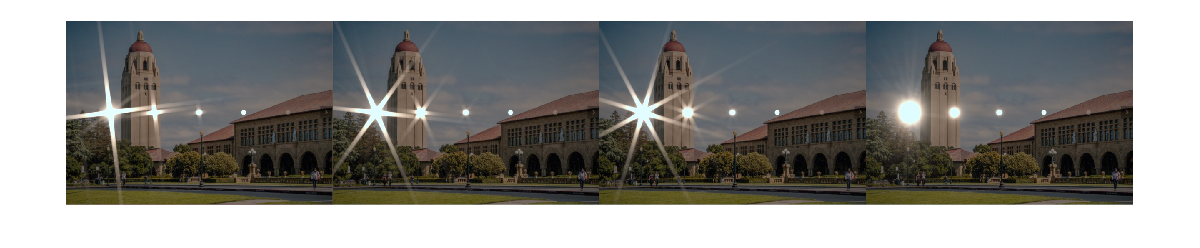

% Try change to dot and line scratches, as you like
nsides = [4 6 8 0];
img = cell(numel(nsides),1);
sensor = [];

for ii = 1:numel(nsides)
    [aperture, params] = wvfAperture(wvf,'nsides',nsides(ii),...
        'dot mean',10, 'dot sd',5, 'dot opacity',0.5,'dot radius',5,...
        'line mean',10, 'line sd', 5, 'line opacity',0.5,'linewidth',2);

    oi = oiSet(oi,'fnumber',1.5);
    oi = oiSet(oi,'focal length',4.38e-3,'m');

    oi = oiCompute(oi, scene,'crop',true,'pixel size',3e-6,'aperture',aperture);

    % To see the flare in the OI, we must use hdr rendering mode.
    oi = oiAdjustIlluminance(oi, 100);
    % oiWindow(oi,'render flag','hdr');

    % To visualize, we used the ip window image
    if isempty(sensor)
        % First time through, create a sensor using this function.
        [ip,sensor] = piRadiance2RGB(oi,'etime',1/10);
    else
        % Next time, use the sensor
        sensor = sensorCompute(sensor,oi);
        ip = ipCompute(ip,sensor);
    end

    img{ii} = ipGet(ip,'srgb');
    % ipWindow(ip);
end
montage(img,'Size',[1, numel(nsides)]);

## END